clear

%initialze & display map
load exampleMaps.mat;
whos *Map*;

  Name              Size               Bytes  Class      Attributes

  complexMap       41x52                2132  logical              
  emptyMap         26x27                 702  logical              
  simpleMap        26x27                 702  logical              
  ternaryMap      501x501            2008008  double               



map = binaryOccupancyMap(simpleMap, 2);
simpleMap

simpleMap = 26×27 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

show(map)
hold on
freespace(10,2) = NaN;
n=0;
for y = 1:1:12
    for x = 0:1:12
    status = checkOccupancy(map, [x,y]);
    if status == 0
        n = n+1;
        freespace(n,1) = x;
        freespace(n,2) = y;
        plot(x, y,'>r', MarkerSize=5)
        %pause(0.5)
    end
    end
end

freespace

freespace =      1     1
     2     1
     3     1
     6     1
     7     1
     8     1
     9     1
    10     1
    11     1
    12     1


status1 = checkOccupancy(map, [5,3])

status1 = 0


% %check for freespace, obstacles, and clean area
% x = x+1;
% status = checkOccupancy(map, [x,y]);
% if status == 0
%     plot(x,y,'>r', MarkerSize=5)
% end
% if status == 1
%     up = y+1;
%     dwn = y-1;
%     s_u = checkOccupancy(map,[x up]);
%     s_d = checkOccupancy(map,[x dwn]);
% end
% hold off







plot(0.5,1,'og', MarkerSize=5)
prm = mobileRobotPRM;
prm.Map = map;
prm.NumNodes = 50;
prm.ConnectionDistance = 10;
path = findpath(prm, [1,1], [8, 12])

path =     1.0000    1.0000
    3.5501    4.3904
    6.5526    9.0880
    8.8525   10.9293
    8.8301   11.7007
    8.0000   12.0000


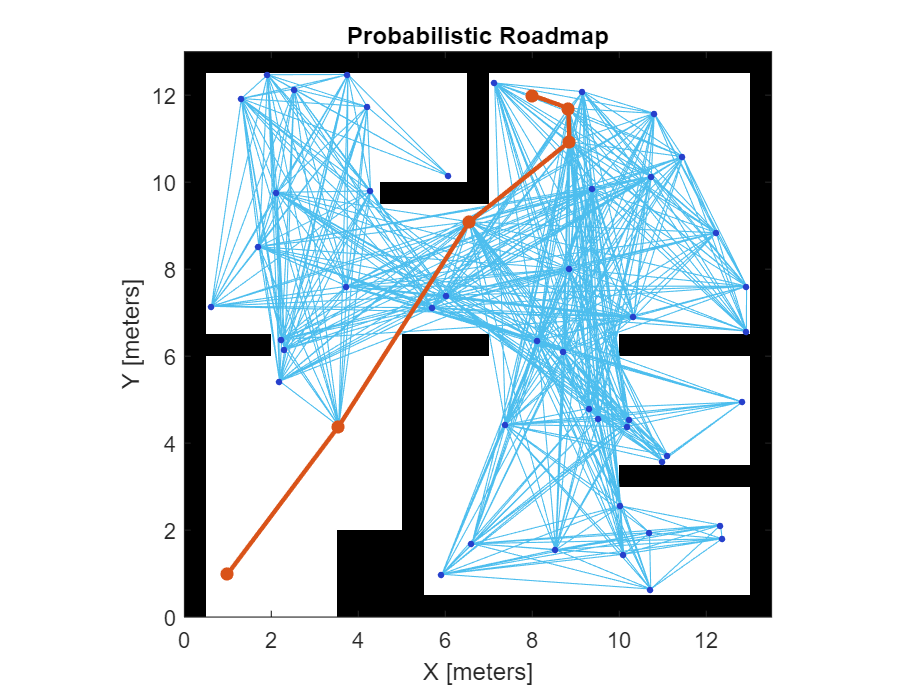

show(prm)

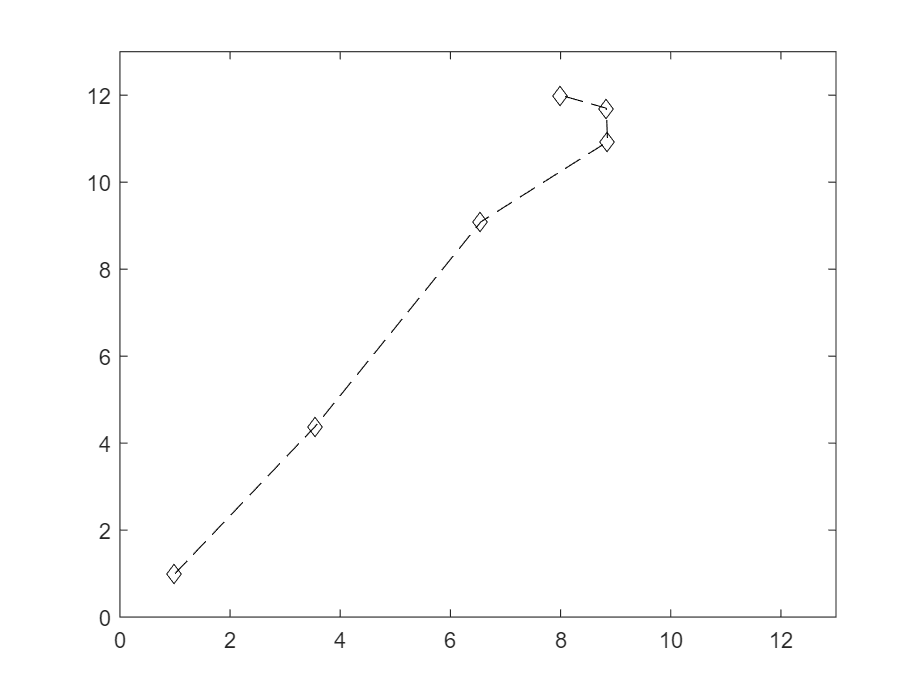

figure
plot(path(:,1), path(:,2),'k--d')
xlim([0 13])
ylim([0 13])


% n = 0;
% y = 1;
% freespace(10,2) = NaN;
% for x = 0:1:12
%     status = checkOccupancy(map, [x,y]);
%     if status == 0
%         n = n+1;
%         freespace(n,1) = x;
%         freespace(n,2) = y;
%     else 
%         y = y+1;
%         x = 0;
%     end
% end
% freespace


%setOccupancy(map, [1,1],1)
% checkOccupancy(map,[1,1])
%map2 = occupancyMap(10,10,1,'grid')